Ejemplo para estudiar algunas de las propiedades de la correlación como una operación entre 2 señales

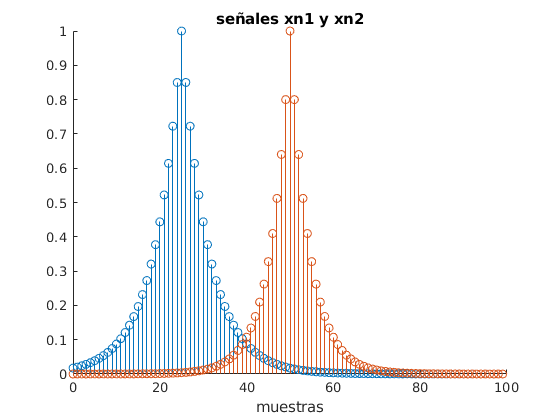

n=0:99;
% Generando señales de prueba
xn1=(0.85.^abs(n-25));
xn2=(0.8.^abs(n-50));
figure()
hold on
stem(n,xn1)
stem(n,xn2)
xlabel('muestras')
title('señales xn1 y xn2')

Ambas señales son muy parecidas pero difieren en la muestra donde ocurre el punto máximo.

Se obtiene la correlación cruzada entre ambas señales

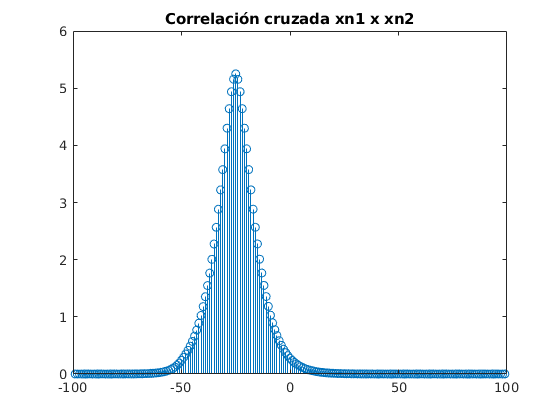

% Cálculos de correlación cruzada
[xc,lag]=xcorr(xn1,xn2);
figure()
stem(lag,xc)
title('Correlación cruzada xn1 x xn2')

[M,I]=max(xc);
fprintf('Máximo: %4.2f posición: %d',M,lag(I))

Máximo: 5.25 posición: -25

El valor de posición=-5 indica que la señal xn1 está adelantada 5 muestras con respecto a xn2

Observe que la correlación cruzada no es conmutativa

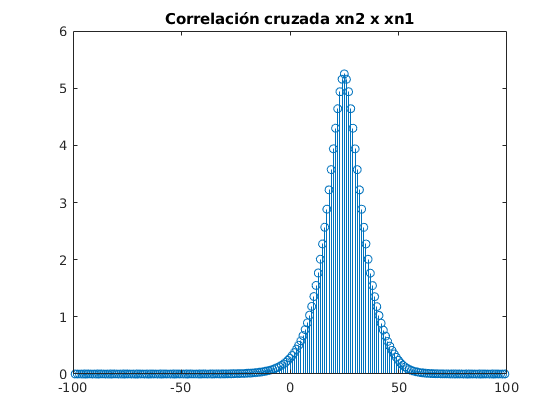

% Cálculos de correlación cruzada
[xc,lag]=xcorr(xn2,xn1);
figure()
stem(lag,xc)
title('Correlación cruzada xn2 x xn1')

[M,I]=max(xc);
fprintf('Máximo: %4.2f posición: %d',M,lag(I))

Máximo: 5.25 posición: 25

En este caso la posición=5 indica que la señal xn2 está en atraso 5 muestras con respecto a xn1.

A partir del cálculo de la correlación cruzada entre dos señales se puede obtener una versión normalizada que no es afectada por las amplitudes de las señales (Ver ayuda de la función xcorr)

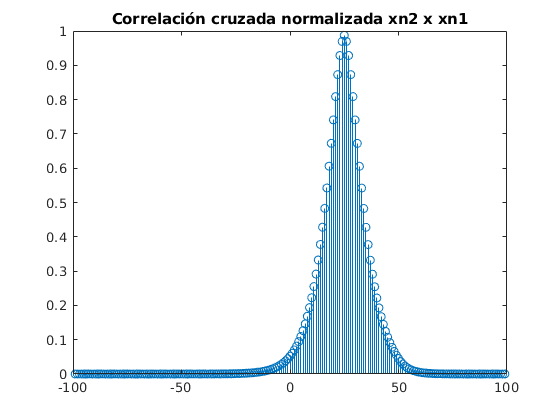

[xc,lag]=xcorr(xn2,xn1,'normalized');
figure()
stem(lag,xc)
title('Correlación cruzada normalizada xn2 x xn1')

[M,I]=max(xc);
fprintf('Máximo: %4.2f posición: %d',M,lag(I))

Máximo: 0.99 posición: 25

A continuación se aplica el coeficiente de correlación, que es otra medida para establecer la similitud entre dos señales

ca=corr(xn1',xn2');
fprintf('Coeficiente de correlación: %4.2f',ca)

Coeficiente de correlación: -0.20

Este valor está entre -1 y 1 indicando la similitud de las señales (ver ayuda de la función corr)